DTFT的有限长序列信号，注意的是我们这里其实我们正是因为有限长度所以才导致我们这里有其他频率

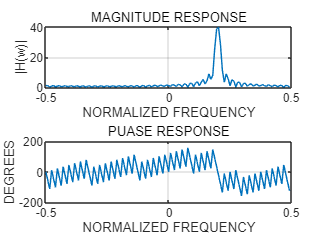

format compact,subplot(111)
a=exp(sqrt(-1)*2*pi/5);%之前这里有一个0.88结果就比较差，我不是非常明白这是为什么
nn=0:40;
xn=a.^nn;
[X,W]=dtft(xn,128);
subplot(211),plot(W/2/pi,abs(X));
grid,title('MAGNITUDE RESPONSE')
xlabel('NORMALIZED FREQUENCY'),ylabel('|H(w)|')
subplot(212),plot(W/2/pi,180/pi*angle(X));grid
xlabel('NORMALIZED FREQUENCY'),ylabel('DEGREES')
title('PUASE RESPONSE')

我们尝试把N增大看看效果如何

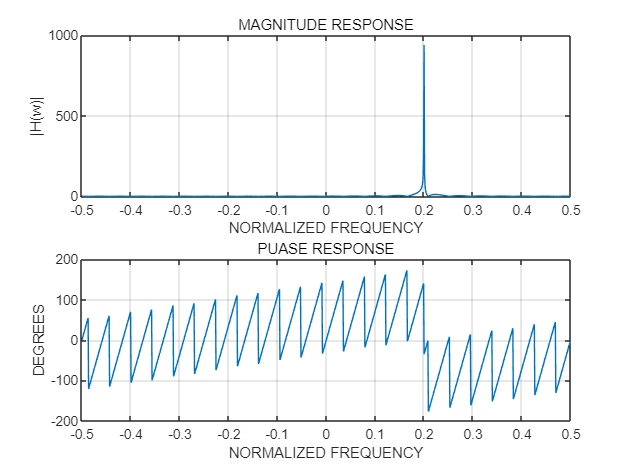

format compact,subplot(111)
a=exp(sqrt(-1)*2*pi/5);%这里也是，我们现在效果非常的好
nn=0:1000;
xn=a.^nn;
[X,W]=dtft(xn,1024);
subplot(211),plot(W/2/pi,abs(X));
grid,title('MAGNITUDE RESPONSE')
xlabel('NORMALIZED FREQUENCY'),ylabel('|H(w)|')
subplot(212),plot(W/2/pi,180/pi*angle(X));grid
xlabel('NORMALIZED FREQUENCY'),ylabel('DEGREES')
title('PUASE RESPONSE')

然后是我们的脉冲信号的DTFT，我们对离散信号熟知脉冲是一个sinc函数，这里我们看看

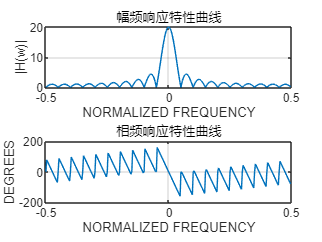

format compact,subplot(111)
a=1;
nn=0:19;xn=a.^nn;
[X,W]=dtft(xn,300);
subplot(211),plot(W/2/pi,abs(X));
grid,title('幅频响应特性曲线')
xlabel('NORMALIZED FREQUENCY'),ylabel('|H(w)|')
subplot(212),plot(W/2/pi,180/pi*angle(X));grid
xlabel('NORMALIZED FREQUENCY'),ylabel('DEGREES')
title('相频响应特性曲线')

这个是其频移特性

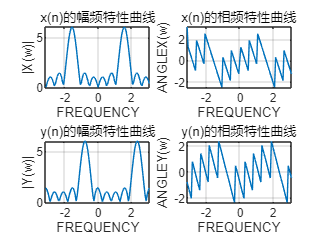

nn = 0:10;    %n的取值范围
x = cos(pi/2*nn);    %x（n）的表达式
y = exp(1i*pi*nn/4).*cos(pi/2*nn);    %y（n）的表达式
[X, Wx] = dtft(x,100);    %对x（n）进行dtft变换
[Y, Wy] = dtft(y,100);    %对y（n）进行dtft变换
hf = figure;
subplot(221);
plot(Wx,abs(X));grid on;  %绘制x（n）的幅频响应特性曲线
title('x(n)的幅频特性曲线');xlabel('FREQUENCY'),ylabel('|X(w)|');
subplot(222);
plot(Wx,angle(X));grid on; %绘制x（n）的相频响应特性曲线
title('x(n)的相频特性曲线');xlabel('FREQUENCY'),ylabel('ANGLE{X(w)}');
subplot(223);
plot(Wy,abs(Y));grid on;   %绘制y（n）的幅频响应特性曲线
title('y(n)的幅频特性曲线');xlabel('FREQUENCY'),ylabel('|Y(w)|');
subplot(224);
plot(Wy,angle(Y));grid on;   %绘制y（n）的相频响应特性曲线
title('y(n)的相频特性曲线');xlabel('FREQUENCY'),ylabel('ANGLE{Y(w)}');